# Verification of Super_Position Theory for RC Circuit

### Super-Position theorem for differential equation

Suppose y1(t) solves the diiferential equation,$\frac{\textrm{dy}}{\textrm{dt}}$ + f(t) = g1(t)

Suppose y2(t) solves the diiferential equation,$\frac{\textrm{dy}}{\textrm{dt}}$ + f(t) = g2(t)

Then y1 + y2 is a solution to $\frac{\textrm{dy}}{\textrm{dt}}$ + f(t) = g1(t) + g2(t)

Proof:

y = y1 + y2

y' = y1' + y2'

y1' + y2' + f(t) * [ y1 + y2 ] = g1(t) + g2(t)

[ y1' + f(t) * y1 ] +  [ y2' + f(t) * y2 ] = g1(t) + g2(t)

g1(t) + g2(t) = g1(t) + g2(t)

Hence Prooved.

### PROOF OF SUPER_POSITION THEOREM 

### With 2 source voltages Vs1 and Vs2

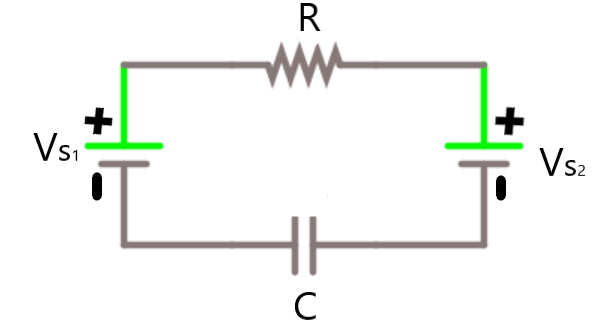

Let Vc be the voltage across the capacitor.

Let Vr be the voltage across the resistor.

Let Vs1 be source voltage 1.

Let Vs2 be source voltage 2.

Let R be the resistance of the resistor and C be the capacitance of the capacitor.

Let q(t) be charge on capacitor,

q(t) = C x Vc(t)

$\frac{\textrm{dq}\left(t\right)}{\textrm{dt}}$ = C x Vc'(t)

Vc'(t) =  $\frac{I\left(t\right)}{C}$  ---- (i)

By Ohm's law, I = $\frac{V}{R}$

By, Kirchoff's voltage law [Sum of voltage around any closed loop is zero],

Vs1 - Vs2 - Vr - Vc(t) = 0

**Vr = Vs1 - Vs2 - Vc(t)**  ---- (ii)

Use (ii) in (i), 

Vc'(t) = $\frac{\textrm{Vs1}-\textrm{Vs2}-\textrm{Vc}\left(t\right)}{R\;x\;C}$

By Euler's method,

**Vc(n+1) = Vc(n) + **$\bigtriangleup$**t x **$\frac{\textrm{Vs1}-\textrm{Vs2}-\textrm{Vc}\left(\mathit{\mathbf{n}}\right)}{\mathit{\mathbf{R}}\;\mathit{\mathbf{x}}\;\mathit{\mathbf{C}}}$  

**I = **$\frac{\textrm{Vs1}-\textrm{Vs2}-\textrm{Vc}\left(\mathbf{t}\right)}{\mathit{\mathbf{R}}\;}$

In this case, let voltage across the resistor, capacitor be Vr_out and Vc_out. Let the total current flowing in the circuit be I_out.

### With source voltage Vs1

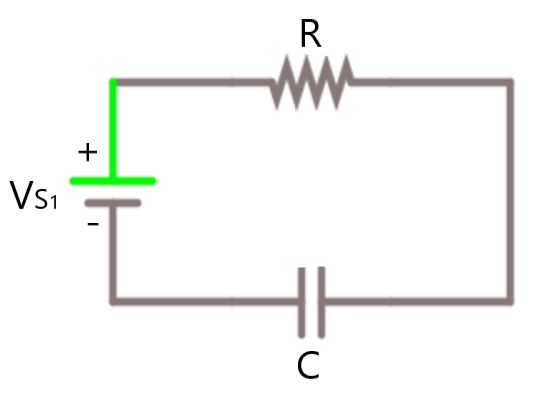

By, Kirchoff's voltage law [Sum of voltage around any closed loop is zero],

Vs1 - Vr - Vc(t) = 0

**Vr = Vs1 - Vc(t)**  ---- (ii)

Use (ii) in (i), 

Vc'(t) = $\frac{\textrm{Vs1}-\textrm{Vc}\left(t\right)}{R\;x\;C}$

By Euler's method,

**Vc(n+1) = Vc(n) + **$\bigtriangleup$**t x **$\frac{\textrm{Vs1}-\textrm{Vc}\left(\mathit{\mathbf{n}}\right)}{\mathit{\mathbf{R}}\;\mathit{\mathbf{x}}\;\mathit{\mathbf{C}}}$  

**I1 = **$\frac{\textrm{Vs1}-\textrm{Vc}\left(\mathbf{t}\right)}{\mathit{\mathbf{R}}\;}$

In this case, let voltage across the resistor, capacitor be Vr_out1 and Vc_out1. Let the total current flowing in the circuit be I1.

### With source voltage Vs2

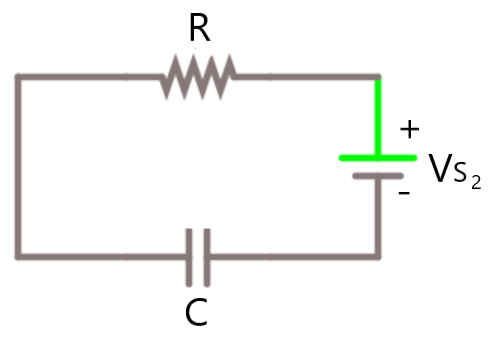

By, Kirchoff's voltage law [Sum of voltage around any closed loop is zero],

-Vs2 - Vr - Vc(t) = 0

**Vr = -Vs2 - Vc(t)**  ---- (ii)

Use (ii) in (i), 

Vc'(t) = $\frac{-\textrm{Vs2}-\textrm{Vc}\left(t\right)}{R\;x\;C}$

By Euler's method,

**Vc(n+1) = Vc(n) + **$\bigtriangleup$**t x **$\frac{-\textrm{Vs2}-\textrm{Vc}\left(\mathit{\mathbf{n}}\right)}{\mathit{\mathbf{R}}\;\mathit{\mathbf{x}}\;\mathit{\mathbf{C}}}$  

**I2 = **$\frac{-\textrm{Vs2}-\textrm{Vc}\left(\mathbf{t}\right)}{\mathit{\mathbf{R}}\;}$

In this case, let voltage across the resistor, capacitor be Vr_out2 and Vc_out2. Let the total current flowing in the circuit be I2.

By super-position theorem,

Vc_out = Vc_out1 + Vc_out2

Vr_out = Vr_out1 + Vr_out2

I_out = I1 + I2

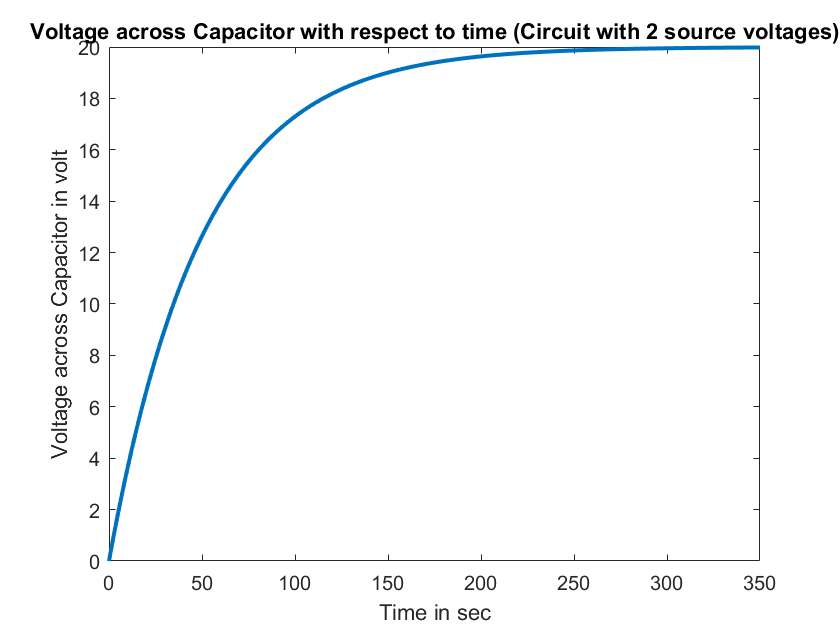

clc;
clear all;
close all;

R = 5;
C = 10;
time_constant = R * C;
% To get a smooth graph we here take 7 times the time constant
% Actually steady state is achieved at 5 times the time constant
T = 7 * time_constant;
dt = 0.01;
t = 0:dt:T;
Vs1 = 30;
Vs2 = 10;
Vc(1) = 0;

for n = 1:(length(t)-1)
Vc(n+1) = Vc(n) + dt*((Vs1 - Vs2 - Vc(n))*(1/(R*C)));
end
Vr = Vs1 - Vs2 - Vc;
I = (Vs1 - Vs2 - Vc) / R;

% Plotting the graph
plot(t,Vc,"LineWidth",2)
title("Voltage across Capacitor with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec")
ylabel("Voltage across Capacitor in volt")

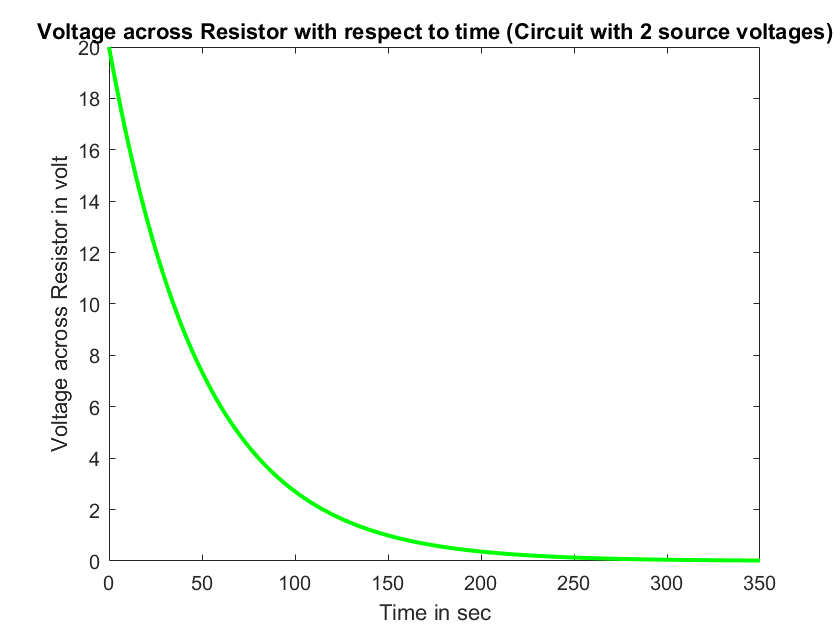


plot(t,Vr,"LineWidth",2,"Color",'green')
title("Voltage across Resistor with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec") 
ylabel("Voltage across Resistor in volt")

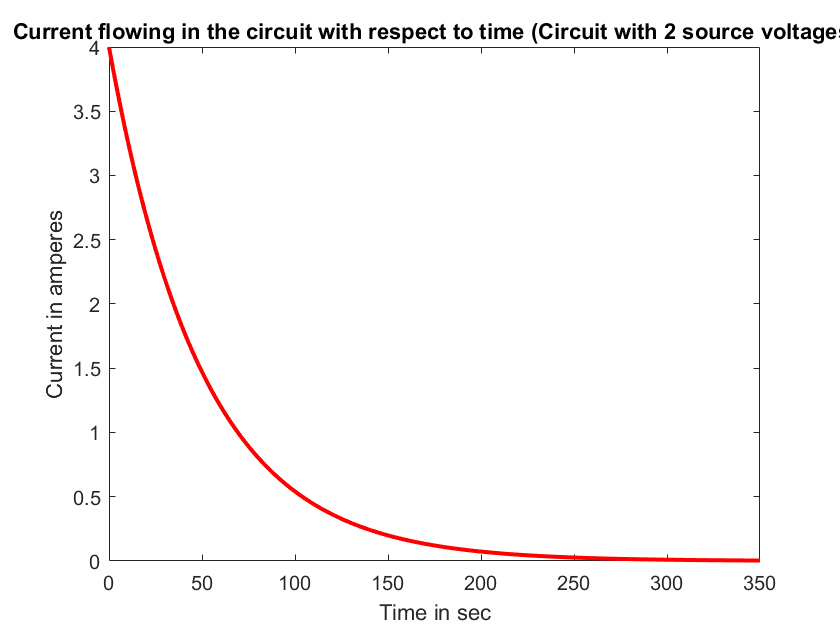

plot(t,I,"LineWidth",2,"Color",'r')
title("Current flowing in the circuit with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec") 
ylabel("Current in amperes")

When one source voltage (Vs1)  is alone connected

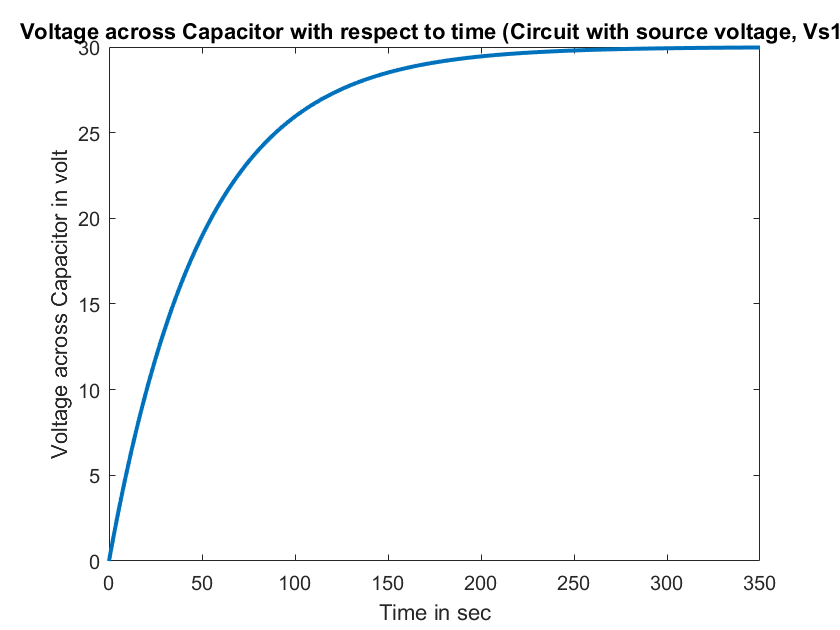

Vc_out1(1) = 0;
for i = 1:(length(t)-1)
    Vc_out1(i+1) = Vc_out1(i) + dt*((Vs1 - Vc_out1(i))*(1/(R*C)));
end
Vr_out1 = Vs1 - Vc_out1;
I1 = (Vs1 - Vc_out1) / R;

% Plotting the graph
plot(t,Vc_out1,"LineWidth",2)
title("Voltage across Capacitor with respect to time (Circuit with source voltage, Vs1)")
xlabel("Time in sec")
ylabel("Voltage across Capacitor in volt")

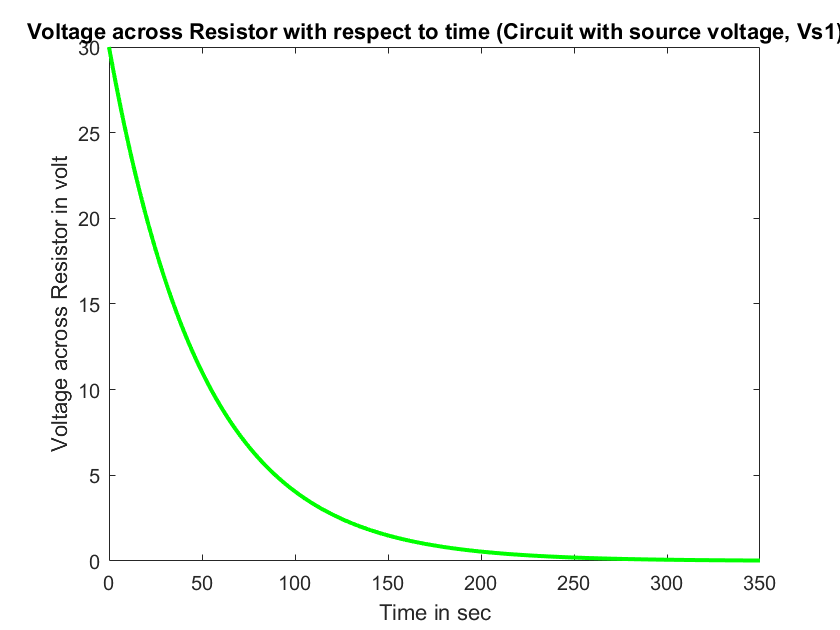

plot(t,Vr_out1,"LineWidth",2,"Color",'green')
title("Voltage across Resistor with respect to time (Circuit with source voltage, Vs1)")
xlabel("Time in sec") 
ylabel("Voltage across Resistor in volt")

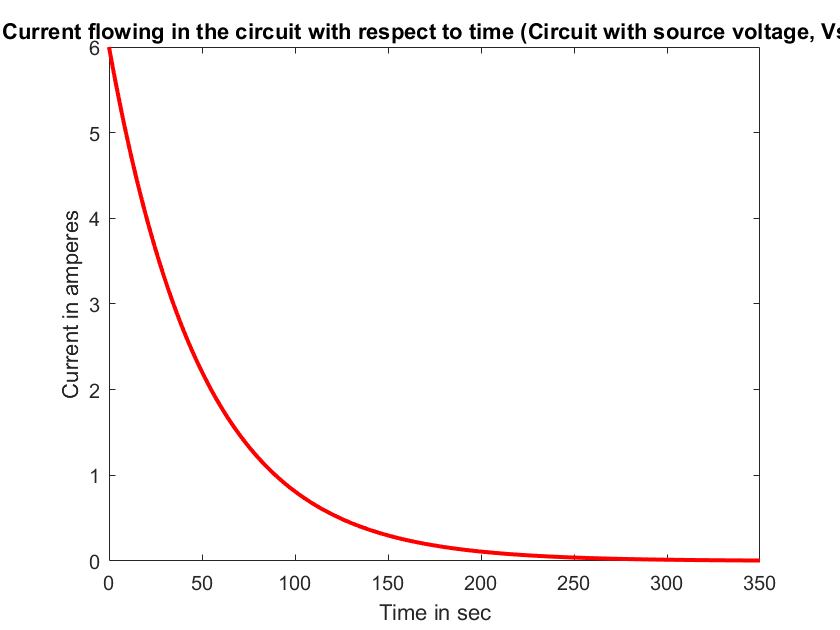

plot(t,I1,"LineWidth",2,"Color",'r')
title("Current flowing in the circuit with respect to time (Circuit with source voltage, Vs1)")
xlabel("Time in sec") 
ylabel("Current in amperes")

When one source voltage (Vs2)  is alone connected

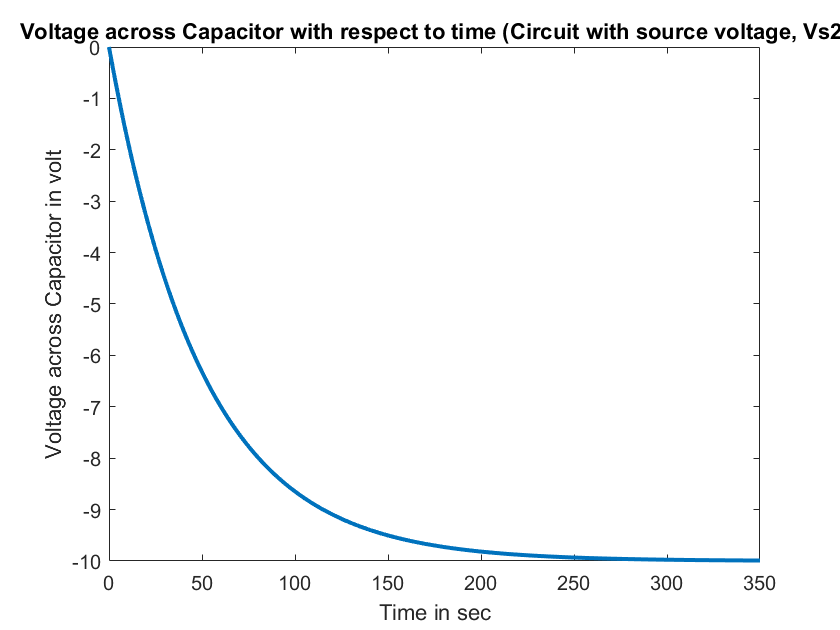

Vc_out2(1) = 0;
for j = 1:(length(t)-1)
    Vc_out2(j+1) = Vc_out2(j) + dt*((-Vs2 - Vc_out2(j))*(1/(R*C)));
end
Vr_out2 = -Vs2 - Vc_out2;
I2 = (-Vs2 - Vc_out2) / R;

% Plotting the graph
plot(t,Vc_out2,"LineWidth",2)
title("Voltage across Capacitor with respect to time (Circuit with source voltage,Vs2)")
xlabel("Time in sec")
ylabel("Voltage across Capacitor in volt")

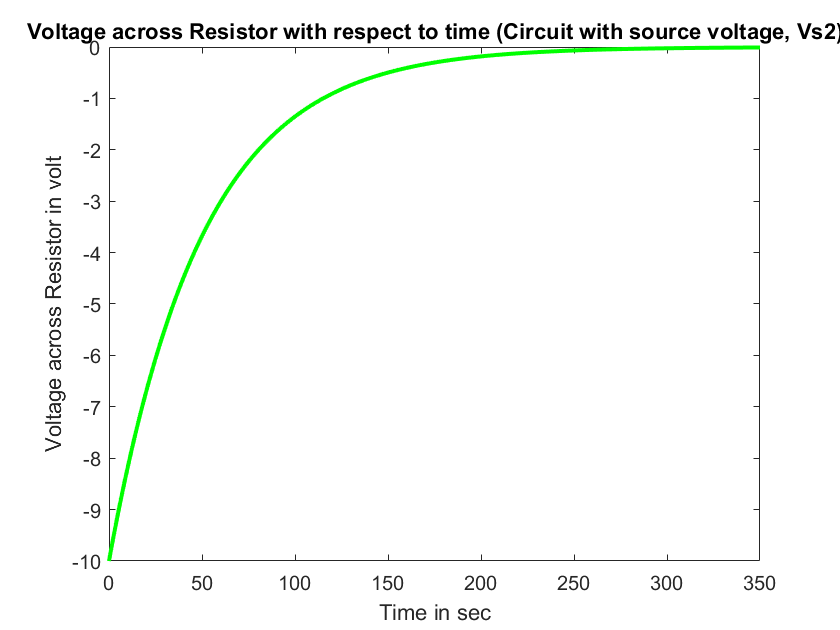

plot(t,Vr_out2,"LineWidth",2,"Color",'green')
title("Voltage across Resistor with respect to time (Circuit with source voltage,Vs2)")
xlabel("Time in sec") 
ylabel("Voltage across Resistor in volt")

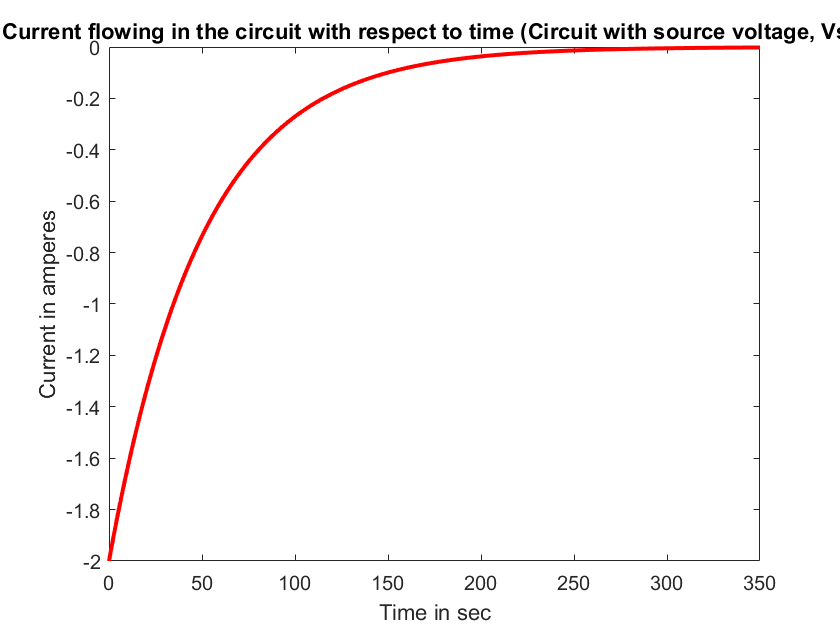

plot(t,I2,"LineWidth",2,"Color",'r')
title("Current flowing in the circuit with respect to time (Circuit with source voltage,Vs2)")
xlabel("Time in sec") 
ylabel("Current in amperes")

Negative voltage in a circuit is voltage that is more negative in polarity than the ground of the circuit.

A voltage source has positive or negative polarity depending on its orientation in a circuit. In the case when a voltage across an element has negative voltage, it just means the negative terminal of the voltmeter is connected to the positive side of the circuit and the positive terminal of the voltmeter is connected to the negative side of the circuit.

It just conveys the orientation, but do not make any effect.  

The negative value of current also shows just the opposite direction of flow of current in the circuit. Negative sign tells the direction and not affect magnitude in any way.

Thus, on summing both the functions, as per the super_position theorem, 

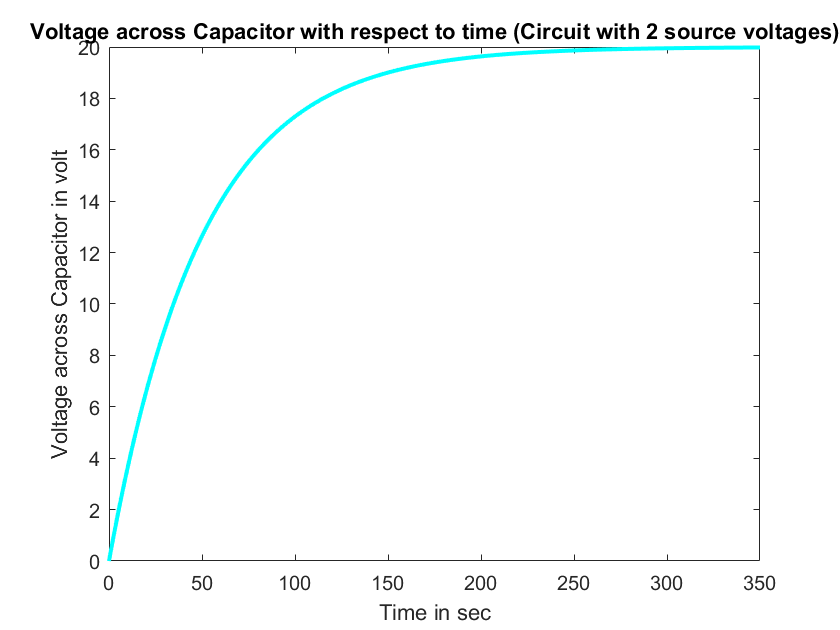

Vc_out = Vc_out1 + Vc_out2;
Vr_out = Vr_out1 + Vr_out2;
I_out = I1 + I2;

plot(t,Vc_out,"LineWidth",2,"Color",'c')
title("Voltage across Capacitor with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec")
ylabel("Voltage across Capacitor in volt")

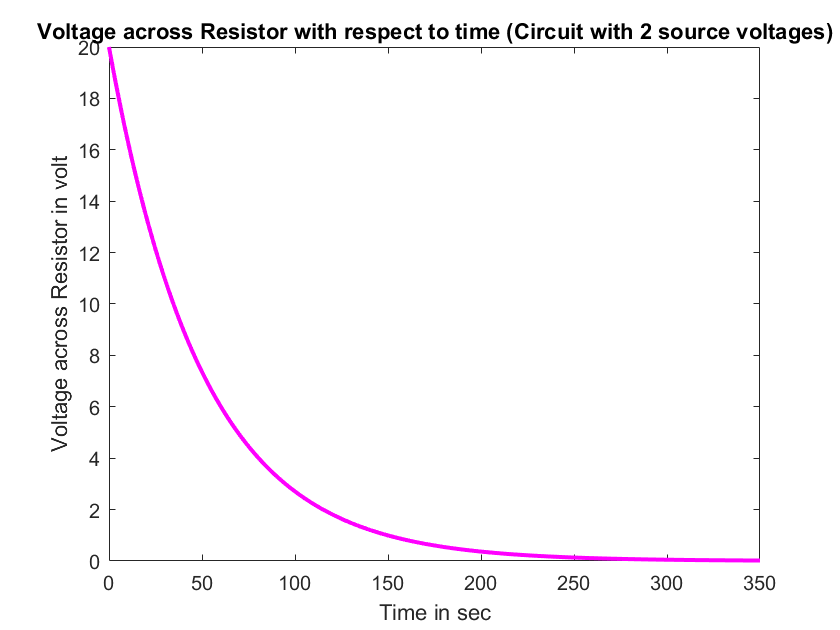

plot(t,Vr_out,"LineWidth",2,"Color",'m')
title("Voltage across Resistor with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec") 
ylabel("Voltage across Resistor in volt")

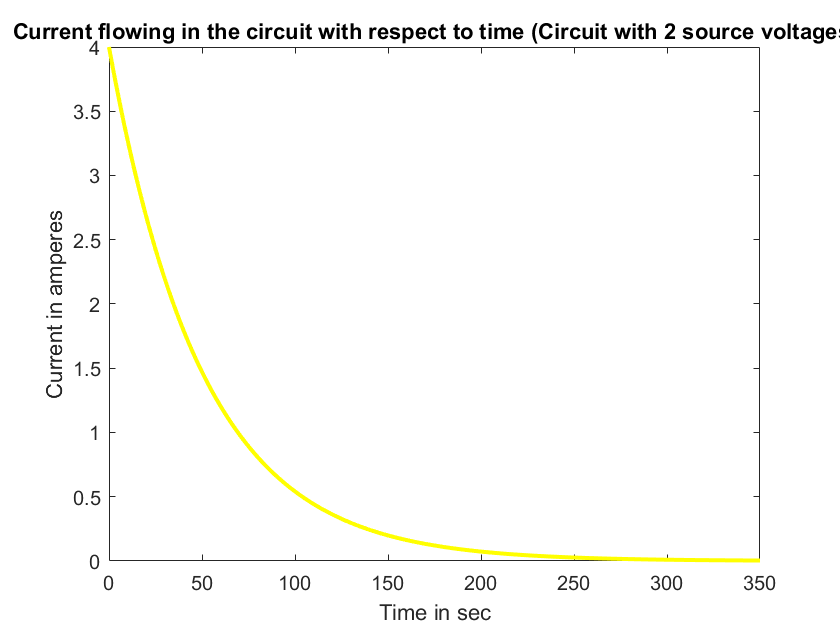

plot(t,I_out,"LineWidth",2,"Color",'y')
title("Current flowing in the circuit with respect to time (Circuit with 2 source voltages)")
xlabel("Time in sec") 
ylabel("Current in amperes")